# Object-Oriented Tools for Fitting Conics and Quadrics

## Introduction

This FEX submission offers a tool set for fitting 2D conics (ellipses, circles, lines,...) as well as 3D quadric surfaces (ellipsoids, spheres, planes, cylinders, cones,...). Each type of fit is represented by an object within a class hierarchy. For each fit type, overloaded methods are provided for generating noisy test data, fitting the data, and visualizing and post-sampling the results. 

Currently, not all curve/surface types in the conic/quadric family are covered by this tool set, although I may add more over time. For now, I provide a subset of the ones that seem to be the most commonly encountered. Similarly, most fitting algorithms used by the tool set are very basic algebraic methods, although I may add more refined algorithms as the need and interest arise.

 Various example uses of these tools are illustrated in the sections below.

## Two Dimensional Fitting

### Fitting an Ellipse

First, we will synthesize noisy samples `xy` of a partial ellipse. To do so, we take advantage of the static method `xysim()` available in the `ellipticalFit` class. This method allows us to generate data for the ellipse, specifying its ground truth center location `[x0,y0]`, its major and minor axis radii `[a,b]`, and its clockwise rotation angle measured in degrees. Additive Gaussian noise with standard deviation s`ig` is added to simulate measurement errors.

clear

[x0,y0]=deal(5,2);  %Center coordinates
[a,b]=deal(20,10);  %Major and minor axis radii
angle=30;           %Rotation angle in degrees

thetaSamps=[-70:5:50,100:5:150]; %Sample angles in degrees
sig=0.3;                         %Error standard deviation

xy=ellipticalFit.xysim([x0,y0],[a,b],angle, thetaSamps, sig); %Generate noisy samples

The sample locations `thetaSamps` correspond to initial azimuthal angles on the unit circle. The circle is stretched, rotated, and translated to achieve the final position of the ellipse, and the sample locations are transformed accordingly.

Next, we will perform a fit to this data, returning the result as an e`llipticalFit` object called `fobj`, and then visually verify the result.

fobj=ellipticalFit(xy), %Perform the fit

fobj =   ellipticalFit with properties:

    center: [4.9855 1.8036]
         a: 20.0655
         b: 10.1999
     angle: 30.3474


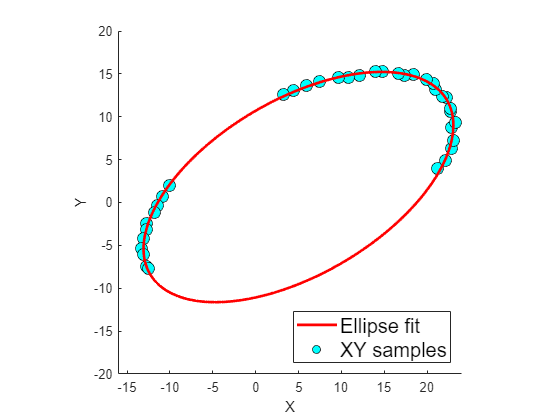


[hFit,hData]=plot(fobj,{'LineWidth',2},{'MarkerFaceColor','c','MarkerEdgeColor','k'}); %Visualize the fit

legend([hFit,hData],'Ellipse fit','XY samples',...
                    'Location','southeast','FontSize',15);
 
hData.SizeData=80;
axis([-16 24 -20 20])

For visual verification, the `plot()` method of the `ellipticalFit` class overlays an implicit function plot of the fitted ellipse onto a scatter plot of the data samples, returning handles `hFit` and `hData` to each respectively. The `plot()` method of the `ellipticalFit` class accepts cell arrays of Name/Value pair arguments to `fimplicit()` and to `scatter()` to control the appearance of each plot component. The output handles may also be used to help generate a plot legend, as well as to make any desired post-adjustments to the appearance of the plot. 

### **Fitting a Circle**

Similar to the example above, we now generate noisy samples of a circular arc, specifying ground truth values for the center and radius of the circle.

clear

[x0,y0]=deal(12,10); %Center coordinates
radius=18;           %Circle radius

thetaSamps=linspace(0,120,10); %Sample angles in degrees
sig=0.6;                       %Error standard deviation

xy=circularFit.xysim([x0,y0], radius, thetaSamps, sig); %Generate noisy samples

Because a circle is a special case of an ellipse, it is interesting to see the impact of parametrizing the arc as a circle as compared to a general ellipse. For data spanning a short arc, we can see how the lower degrees of freedom in the circular parametrization leads to a substantially more accurate estimate of the data's true underlying geometry.

fobjEllipse = ellipticalFit(xy);
fobjCirc    = circularFit(xy),

fobjCirc =   circularFit with properties:

    center: [12.3120 10.2290]
    radius: 17.5688


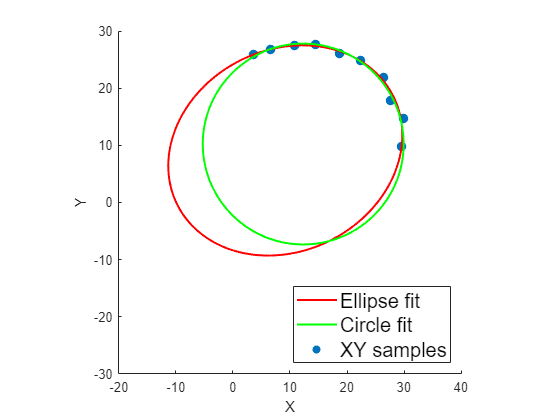


[hE,hD]=plot(fobjEllipse,{'Color','r'}); %Visualize ellipse fit

hold on
 hC=showfit(fobjCirc,'Color','g'); %Add the fitted circle to the plot
hold off

legend([hE,hC,hD],'Ellipse fit','Circle fit', 'XY samples',...
                   'Location','southeast','FontSize',15);
                        
axis([-20 40 -30 30])

The usage of the `plot()` method is the same for circle fit objects as for ellipse fit objects. This example also shows how the overloaded `plot()` and the `showfit()` methods of the fit objects can be used in concert to overlay multiple fits.

### Fitting a 2D Line Segment

Here, we will fit noisy samples of a line segment, generated as follows. Sample locations are generated by taking affine combinations `(1-t(i))*p1 + t(i)*p2` of two fixed points `p1` and `p2`.

clear

p1=[-1,0];  p2=[1,+1.5];  %Simulated line segment end points

t=linspace(0,1,8); % Sample locations along line: t=0 at p1 , t=1 at p2.
sig=0.1;           % Error standard deviation

xy=linear2dFit.xysim(p1, p2, t, sig); %Generate noisy samples

Similar to earlier examples, we generate a fit object and use its plot method to visualize the fit.

fobjLine=linear2dFit(xy),

fobjLine =   linear2dFit with properties:

    p1: [-1.1053 -0.0164]
    p2: [0.9704 1.4707]


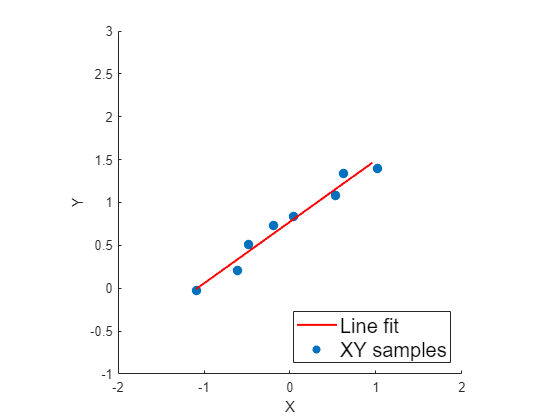


[hL,hD]=plot(fobjLine); %Visualize ellipse fit


legend([hL,hD],'Line fit', 'XY samples', 'Location','southeast','FontSize',15);
axis([-2,2,-1,+3])

## Three Dimensional Fitting

### Fitting an Ellipsoid

In analogy with 2D ellipse fitting, the tool set also provides routines for fitting 3D ellipsoids. The steps for generating simulated data parallel those for the 2D case. In addition to providing ground truth center coordinates, the different axial radii `[a,b,c]` are to be provided in descending order. The orientation of the ellipsoid is specified with a set of yaw, pitch, and roll angles `[y,p,r]` measured in degrees. To achieve the final pose, the yaw, pitch, and roll are applied to an initial, unrotated version of the ellipsoid in which the axis radii `[a,b,c]` are aligned with the `[x,y,z]` axes respectively.

clear

[x0,y0,z0]=deal(5,2,7);  %Center coordinates
[a,b0,c]=deal(20,10,5);   %Axis radii
[y,p,r]=deal(40,-30,50); %Yaw, pitch, and roll angles specifying  ellipsoid orientation (in degrees).

azimuthalSamps=0:10:270;  %Azimuthal angles of samples
elevationSamps=-40:10:40; %Elevation angles of samples
sig=0.3;                  %Error standard deviation

xyz=ellipsoidalFit.xyzsim([x0,y0,z0],[a,b0,c],[y,p,r],...
                         azimuthalSamps, elevationSamps, sig); %Generate noisy samples

In the above, the vectors `azimuthalSamps` and `elevationSamps` are used to specify a curvilinear lattice of sample locations on the surface of the ellipsoid. These specify initial azimuthal and elevation coordinates of samples on the unit sphere. As in the 2D case, a stretch, rotation and translation are applied to bring the samples to their final positions.

Performing and plotting the fit follows the same syntax as before.

fobjEllipsoid=ellipsoidalFit(xyz), %Perform the fit

fobjEllipsoid =   ellipsoidalFit with properties:

    center: [5.0645 1.9843 6.9883]
         a: 20.0568
         b: 10.0690
         c: 4.9855
       yaw: 40.0138
     pitch: -30.0244
      roll: 50.0115


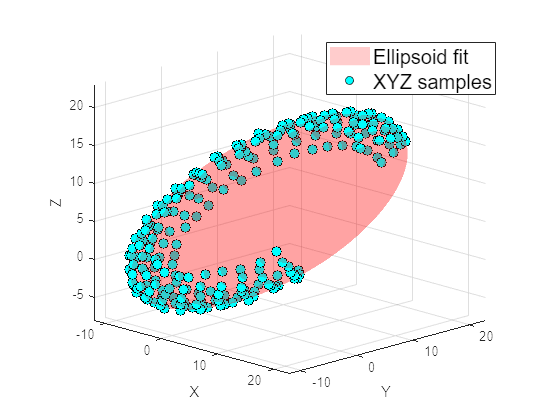


[hFit,hData]=plot(fobjEllipsoid,{'FaceAlpha',0.2},{'MarkerFaceColor','c','MarkerEdgeColor','k'}); %Visualize the fit

legend([hFit,hData],'Ellipsoid fit','XYZ samples',...
                    'Location','northeast','FontSize',15);

axis([-12,+23,-12,+23,-8,+23]); view([45,16])

### Fitting a Sphere

Simulating samples of a sphere proceeds much the same as for an ellipsoid, except fewer geometric parameters are involved.

clear

[x0,y0,z0]=deal(5,2,7);  %Center coordinates
radius=20;               %Sphere radius

azimuthalSamps=linspace(0,80,10);  %Azimuthal angles of samples
elevationSamps=(-30:10:10);        %Elevation angles of samples
sig=0.3;                           %Error standard deviation

xyz=sphericalFit.xyzsim([x0,y0,z0],radius,...
                         azimuthalSamps, elevationSamps, sig); %Generate noisy samples

Below we compare an ellipsoid fit to a sphere fit in analogy with our earlier 2D example of circle versus ellipse.

fobjEllipsoid=ellipsoidalFit(xyz); %Perform ellipse and sphere fits
fobjSphere=sphericalFit(xyz), 

fobjSphere =   sphericalFit with properties:

    center: [4.9112 2.0040 7.1260]
    radius: 20.1019


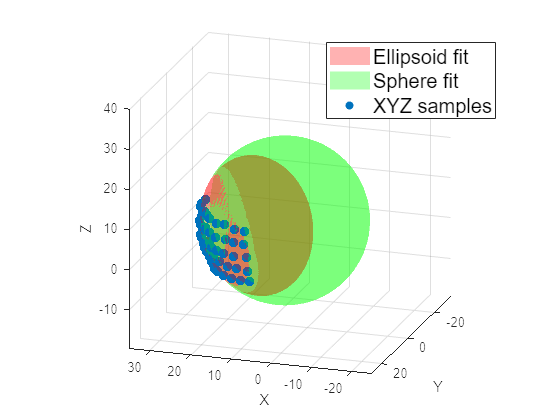


[hE,hData]=plot(fobjEllipsoid); %Visualize the fit

hold on 
 hS=showfit(fobjSphere,'FaceAlpha',0.3,'FaceColor','g');
hold off

legend([hE,hS,hData],'Ellipsoid fit','Sphere fit','XYZ samples',...
                      'Location','northeast','FontSize',15);
  
view([-161.9 18.6])
xlim([-25.0 35.0])
ylim([-32.0 28.0])
zlim([-19.7 40.3])

### Fitting a Circular Cylinder

Generating noisy samples for a circular cylinder is similar to the case of an ellipsoid. Due to circular symmetry, however, only yaw and pitch angles are needed to specify the cylinder's orientation. Also the lattice coordinates of the surface samples are specified in cylindrical coordinates, as opposed to spherical.

clear

[x0,y0,z0]=deal(5,2,7);  %Center coordinates
radius=20;               %Axis radii
[y,p]=deal(30,-25);      %Yaw and pitch angles (in degrees)

azimuthalSamps=linspace(0,360,30);      %Azimuthal angles of samples
axialSamps=linspace(-radius,radius,6);  %Samples length-wise along the cylinder
sig=0.6;                                %Error standard deviation

xyz=cylindricalFit.xyzsim([x0,y0,z0],radius,[y,p],...
                          azimuthalSamps,axialSamps, sig); %Generate noisy samples

Unlike other fit types, the default  cylinder fitting routine is semi-iterative. To estimate the 3D cylinder axis direction, an iterative approach based on `fminsearch` is used,

fobjCyl=cylindricalFit(xyz), %Perform cylinder fit

fobjCyl =   cylindricalFit with properties:

    center: [4.9633 2.0225 6.9917]
    radius: 20.0105
    height: 41.2559
       yaw: 29.9977
     pitch: -24.6652


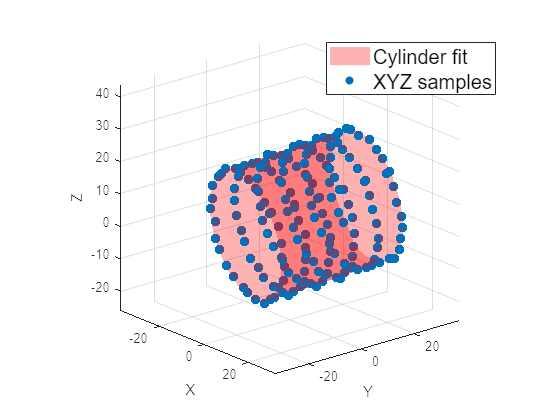



[hFit,hData]=plot(fobjCyl); %Visualize the fit


legend([hFit,hData],  'Cylinder fit','XYZ samples',...
                      'Location','northeast','FontSize',15);

xlim([-37.5 32.5]); ylim([-32.9 37.1]); zlim([-26.1 43.9]); view([50.0 20.0])

*Important**:* the height of the cylinder is ill-defined, since one cannot know what portion of its possibly infinite length is covered by the `xyz` samples. Likewise, the position of its center is well-defined only up to a translation along the cylinder axis. The code sets the center half way between the extreme-most samples along the estimated axis and the height is set as the axial distance between these points.

### Fitting a Right Circular Cone

Simulating the surface fit of a right circular cone follows a very similar procedure to that of a cylinder. Noisy surface samples are generated by specifying their ground truth azimuthal and axial locations:

clear

[x0,y0,z0]=deal(0,-20,-10);  %Cone vertex coordinates
cone_angle=30;               %Angle at the vertex from axis to surface (in degrees)
[y,p]=deal(45,-25);          %Yaw and pitch angles (in degrees)

azimuthalSamps=linspace(0,360,6);   %Azimuthal angles of samples
axialSamps=linspace(20,30,5);       %Samples length-wise along the cone
sig=0.2;                            %Error standard deviation

xyz=rightcircularconeFit.xyzsim([x0,y0,z0],cone_angle,[y,p],...
                                azimuthalSamps,axialSamps, sig); %Generate noisy samples

Also, as was the case for cylinders, the fitting of a cone uses a semi-iterative procedure based on `fminsearch.`

fobjCone=rightcircularconeFit(xyz), %Perform cylinder fit

fobjCone =   rightcircularconeFit with properties:

        vertex: [0.2058 -20.1460 -9.7738]
    cone_angle: 30.1584
        height: 29.9442
           yaw: 45.5722
         pitch: -24.7644


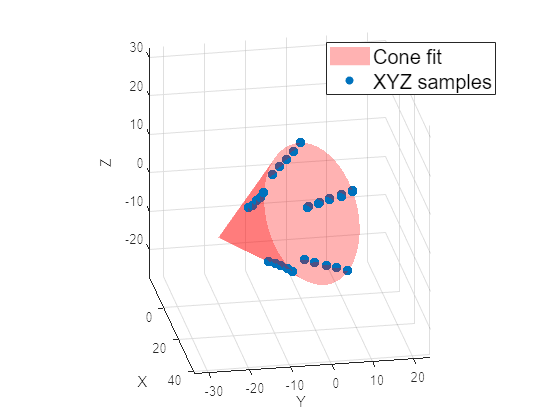



[hFit,hData]=plot(fobjCone); %Visualize the fit


legend([hFit,hData],  'Cone fit','XYZ samples',...
                      'Location','northeast','FontSize',15);

xlim([-19.5 41.8]); ylim([-33.4 24.2]); zlim([-27.2 32.6])
view([79.7 22.7])

*Important**:* Similar to the case of a cylinder, the fitted height of the cone is ill-defined, since one cannot know what portion of its possibly infinite length is covered by the `xyz` samples. The code simply sets the height as the axial distance from the vertex to the most remote point.

### Fitting a Plane

For plane fitting, the data simulation method `planarFit.xyzsim()` generates samples on a lattice covering a parallelogram in 3D space. The sample locations are of the form `b0+t1(i)*b1 +t2(j)*b2 `where `b0, b1`, and `b2` are fixed 3D vectors.


b0=[1,0,0]; %Plane reference point
b1=[0;1;1]; %Plane basis vector
b2=[1;0;1]; %Plane basis vector

t1=linspace(-10,10,8); % Grid coordinates along basis1
t2=linspace(-15,15,5); % Grid coordinates along basis2
sig=0.8;               % Error standard deviation

xyz=planarFit.xyzsim(b0,b1,b2,t1,t2,sig); %Samples are at b0+t1(i)*b1 +t2(j)*b2

The fit reports the normal vector to the plane of the samples, as well as the distance `d` of the plane from the 3D origin along the direction of the normal.

fobjPlane=planarFit(xyz), %Perform plane fit

fobjPlane =   planarFit with properties:

      normal: [-0.5580 -0.5967 0.5767]
    distance: -0.6398


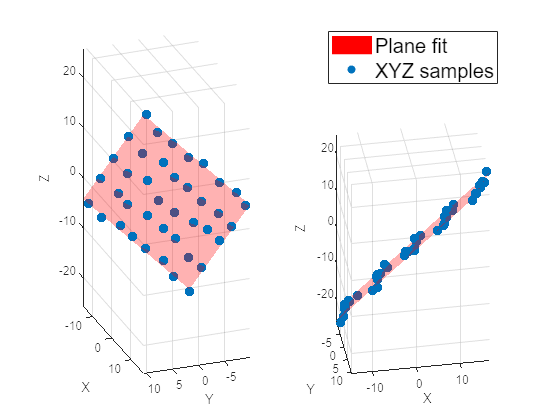


for i=1:2
    subplot(1,2,i);
    [hL,hD]=plot(fobjPlane); %Visualize the fit
end

legend([hL,hD],'Plane fit', 'XYZ samples', 'Location','northoutside','FontSize',15);
subplot(1,2,1)
view([-69.5 -24.6])
subplot(1,2,2)
view([9.6 -35.2])

### Fitting a 3D Line Segment

Although a 3D line is not quadric surface, strictly speaking, the tool set handles this case for the sake of symmetry with the 2D tool set, and because it is a common case of interest. As in the 2D case, samples are generated by taking affine combinations of two specified points `p1` and `p2`.

clear; 

p1=[-1,0,0];  p2=[1,+1.5,2];  %Simulated line segment end points

t=linspace(0,1,8); % Sample locations along line: t=0 at p1 , t=1 at p2.
sig=0.1;           % Error standard deviation

xyz=linear3dFit.xyzsim(p1, p2, t, sig); %Generate noisy samples

The syntax for fitting is analogous to other examples:

fobjLine=linear3dFit(xyz),

fobjLine =   linear3dFit with properties:

    p1: [-1.1224 0.0156 0.0319]
    p2: [0.9729 1.4339 1.9407]


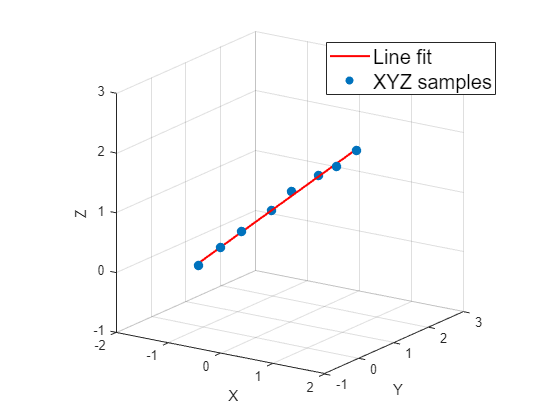


figure;
[hL,hD]=plot(fobjLine,{'LineWidth',1.5,'Color','r'},{'SizeData',50}); %Visualize line fit

legend([hL,hD],'Line fit', 'XYZ samples', 'Location','northeast','FontSize',15);

axis([-2,2,-1,+3,-1,+3]); view([33.77 17.40])

## Post-Fit Processing: Sampling the Fitted Curve or Surface

The various fit objects in the class hierarchy have a `sample()` method that can be used to obtain points on the curves or surfaces generated by a fit. The help documentation gives the input syntax for these methods for each class of fit. Typically, sampling locations are specified in the same way as with  the `xysim()` and `xyzsim()` static methods illustrated earlier. Below are several examples.

### **Post-Sampling an Ellipse Fit**

Here, we fit relatively noisy samples of an ellipse,

clear

xyInput=ellipticalFit.xysim([4,5],[20,10],45, (0:10:360), 2); %Simulate noisy samples

fobj=ellipticalFit(xyInput); %Perform the fit

[hFit,hData]=plot(fobj,{},{'MarkerFaceColor','none','MarkerEdgeColor','b','SizeData',20}); %Visualize 
 
xlim([-16.7 37.0])
ylim([-18.7 23.6])

 and then post-sample more regularly around the ellipse.

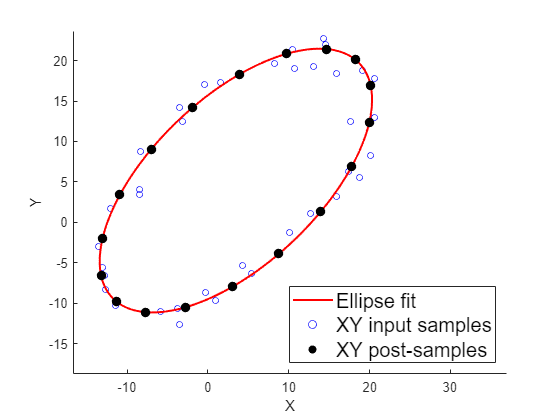

xyPost=fobj.sample(0:20:360); %post-samples

hold on
hPost=scatter(xyPost{:},'filled','k','SizeData',50);
hold off

legend([hFit,hData,hPost],'Ellipse fit','XY input samples','XY post-samples',...
                           'Location','southeast','FontSize',15);

### **Post-Sampling a Cylinder Fit**

Here, we fit a cylinder to samples of a helical spiral,

clear

R= [-0.6468    0.5740   -0.5022   %Rotation matrix
    -0.5073   -0.8155   -0.2786
    -0.5694    0.0745    0.8187];

theta=0:10:3*360;

xyzInput=R*[cosd(theta);sind(theta);theta/360]; %Helical input samples

fobj=cylindricalFit(xyzInput); %Perform the fit

[hFit,hData]=plot(fobj,{},{'MarkerFaceColor','g','MarkerEdgeColor','b','SizeData',20}); %Visualize 

xlim([-2.38 0.87]); ylim([-1.84 1.07]); zlim([-0.47 3.10]); view([18.90 17.00])

 and then extract samples length-wise along the cylinder,

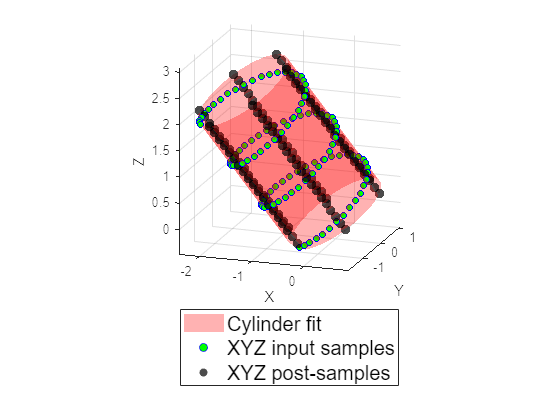


xyzPost=fobj.sample(0:60:360, linspace(0,fobj.height,20)); %Post-samples

hold on
hPost=scatter3(xyzPost{:},'filled','k','SizeData',50,'MarkerFaceAlpha',0.7);
hold off

legend([hFit,hData,hPost],'Cylinder fit','XYZ input samples','XYZ post-samples',...
                          'Location','southoutside','FontSize',15);

### **Post-Sampling a Cone Fit**

Here, we fit spiraling samples on the surface of a cone,

clear

R= [-0.6468    0.5740   -0.5022   %Rotation matrix
    -0.5073   -0.8155   -0.2786
    -0.5694    0.0745    0.8187];

theta=0:10:3*360;

r=linspace(0,1, numel(theta));

xyzInput=R*[r.*cosd(theta);r.*sind(theta);theta/360]; %Helical input samples

fobj=rightcircularconeFit(xyzInput); %Perform the fit

[hFit,hData]=plot(fobj,{},{'MarkerFaceColor','g','MarkerEdgeColor','b','SizeData',20}); %Visualize 

xlim([-2.38 0.87]); ylim([-1.84 1.07]); zlim([-0.47 3.10]); view([215.52 5.90])

 and then extract samples length-wise along the cone,

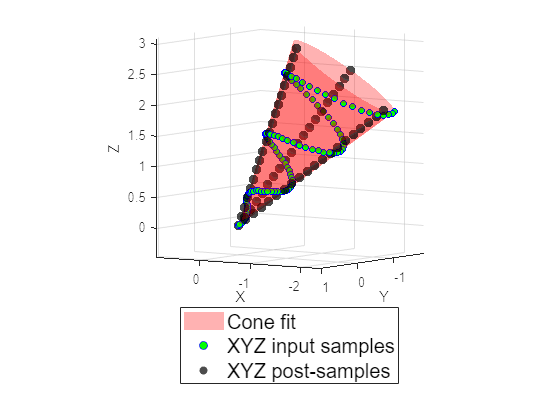


xyzPost=fobj.sample(0:120:360, linspace(0,fobj.height,20)); %Post-samples

hold on
hPost=scatter3(xyzPost{:},'filled','k','SizeData',50,'MarkerFaceAlpha',0.7);
hold off

legend([hFit,hData,hPost],'Cone fit','XYZ input samples','XYZ post-samples',...
                          'Location','southoutside','FontSize',15); 

### **Post-Sampling a Plane Fit**

In this example, after fitting a plane, 

clear

b0=[1,0,0];  t=linspace(-10,10,8); 

xyzInput=planarFit.xyzsim(b0,[0;1;1],[1;0;1],t,t,5); %Input samples

fobj=planarFit(xyzInput); %Perform the fit

[hFit,hData]=plot(fobj,{'MeshDensity',40},...
                       {'MarkerFaceColor','g','MarkerEdgeColor','b','SizeData',20}); %Visualize 

view([-47.9 3.6])

we show how to resample it along lines parallel and perpendicular to the x-z plane.

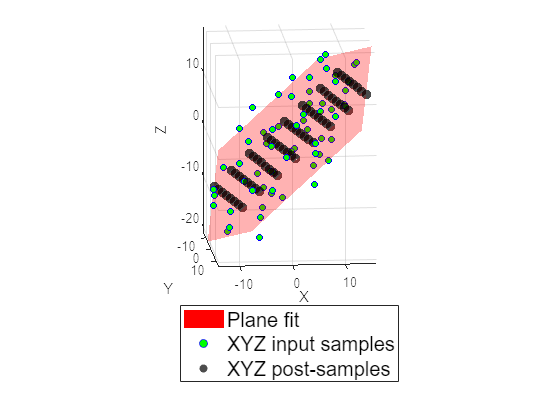

b1=cross([0,1,0],fobj.normal); %Make one sampling direction parallel to x-z plane
b2=[];                         %Make the other direction orthogonal to b1

xyzPost=fobj.sample(b0,b1,b2,2*t,t); %Post-samples

hold on
hPost=scatter3(xyzPost{:},'filled','k','SizeData',50,'MarkerFaceAlpha',0.7); view([5.3 -12.8])
hold off

legend([hFit,hData,hPost],'Plane fit','XYZ input samples','XYZ post-samples',...
                          'Location','southoutside','FontSize',15);

## Ground Truth Objects

All the objects have a `groundtruth()` static method allowing one to generate a conic or quadric surface with geometry specified in advance. This is useful for viewing what a perfect fit would look like. 

### Ellipse Fit versus Ground Truth

Similar to earlier examples, we first generate simulated noisy samples of an ellipse,

clear

[x0,y0]=deal(5,2);  %Center coordinates
[a,b]=deal(15,7);  %Major and minor axis radii
angle=20;           %Rotation angle in degrees

thetaSamps=-180:20:90; %Sample angles in degrees
sig=2;                 %Error standard deviation

xy=ellipticalFit.xysim([x0,y0],[a,b],angle, thetaSamps, sig); %Generate noisy samples

Next, we generate a ground truth object and plot,

gtobj=ellipticalFit.groundtruth(xy, [x0,y0],[a,b],angle); %Ground truth object

subplot(2,1,1)
[hTruth,hData]=plot(gtobj,{'Color','k','LineWidth',2},...
                          {'MarkerFaceColor','c','MarkerEdgeColor','k'}); %Visualize ground truth
legend([hTruth,hData],'Ground Truth','XY samples',...
                      'Location','eastoutside','FontSize',15);
 axis([-16 24 -20 20])

Or, if desired, we can add an actual ellipse fit on top of the data and ground truth locus,

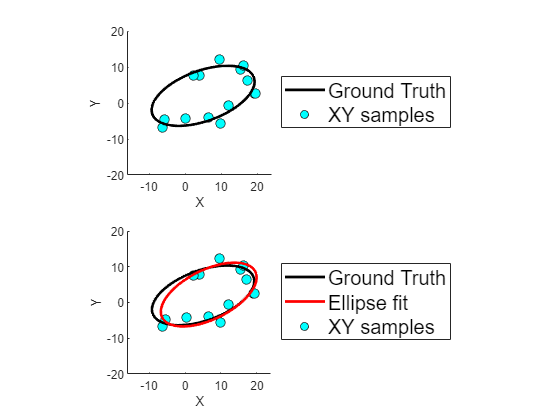

subplot(2,1,2)
[hTruth,hData]=plot(gtobj,{'Color','k','LineWidth',2},...
                          {'MarkerFaceColor','c','MarkerEdgeColor','k'}); 
hold on
hFit = showfit(ellipticalFit(xy), 'Color','r','LineWidth',2); %Visualize the fit
hold off

legend([hTruth,hFit,hData],'Ground Truth','Ellipse fit','XY samples',...
                    'Location','eastoutside','FontSize',15);

axis([-16 24 -20 20])

### Plotting with "No-Data" Objects

A ground truth object does not actually have to be given any coordinate samples. Ground truth objects empty of  samples (or "no-data" objects) can be useful simply for plotting conics,

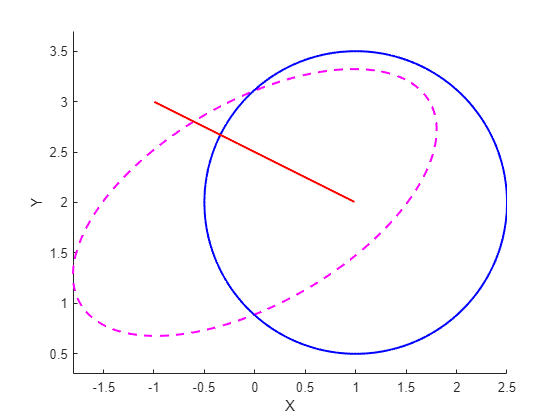

clear
 
[eCenter,eAB,eAngle]=deal([0 2] , [2 1], 30);    %Ellipse parameters
[cCenter,cRadius]=deal([1 2], 1.5);              %Circle parameters
        [p1,p2]=deal([-1 3], [1 2]);             %Line tips
        
     
gtEllip=ellipticalFit.groundtruth([],eCenter,eAB,eAngle);     %Data-less ground truth objects
gtCirc=circularFit.groundtruth([], cCenter, cRadius);
gtLine=linear2dFit.groundtruth([], p1, p2);

figure
hold on
 plot(gtEllip,{'Color','m','LineStyle','--'}); 
 plot(gtCirc,{'Color', 'b'}); 
 plot(gtLine,{'Color', 'r'})
hold off

and likewse 3D quadrics as well,

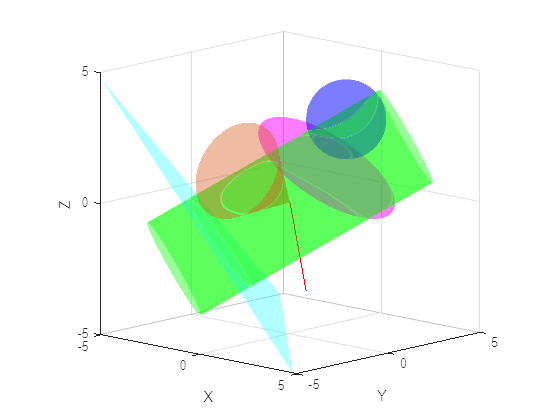

clear
 
[cCenter,cRadius,cHeight,cYP,cAngle]=...
                           deal([0 0 0], 2, 10, [45 -30],30);  %Cylinder/Cone parameters
[pNormal,pDistance]=deal([1 1 1], -3);                         %Plane parameters
[eCenter,eABC,eYPR]=deal([0 2 1] , [3 2 1], [20 30 0]);        %Ellipse parameters
[sCenter,sRadius]=deal([1 2 3], 1.5);                          %Sphere parameters
          [p1,p2]=deal([0 0 0], [0 1 -4]);                     %Line tips
        

gtCyl=cylindricalFit.groundtruth([],cCenter,cRadius,cHeight,cYP); %Data-less ground truth objects
gtCone=rightcircularconeFit.groundtruth([],cCenter,cAngle,cHeight/3,cYP.*[-2,1]);
gtPlane=planarFit.groundtruth([],pNormal,pDistance);
gtEllip=ellipsoidalFit.groundtruth([],eCenter,eABC,eYPR);    
gtSphere=sphericalFit.groundtruth([], sCenter,sRadius);
gtLine=linear3dFit.groundtruth([], p1, p2);


figure
 hold on
 plot(gtCyl,     {'FaceColor', 'g','FaceAlpha',0.4});
 plot(gtCone,    {'FaceColor', [0.85, 0.33, 0.10],'FaceAlpha',0.4});
 plot(gtPlane,   {'FaceColor', 'c'}); 
 plot(gtEllip,   {'FaceColor', 'm'}); 
 plot(gtSphere,  {'FaceColor', 'b'}); 
 plot(gtLine,    {'Color', 'r'});
 view([43.03 12.32])
hold off

## Advanced Topics

This section is devoted to some additional topics, which make more advanced use of the toolkit.

### Fitting a 2D Shape to 3D Points

In some cases, one might wish to fit a 2D shape which is sampled in 3D space. The approach that is needed is to first fit a plane to the given samples, then project the samples into a 2D coordinate system in this plane. Once projected into 2D, the tools for 2D fitting discussed in previous sections can be applied freely. 

This approach is illustrated below for the case of an ellipse fit from 3D sample points. Note how the `planarFit` class methods `project2D` and `unproject3D` are used to facilitate the necessary coordinate transformations to 2D and back.

clear

[x0,y0]=deal(5,2);  %Center coordinates
[a,b]=deal(20,10);  %Major and minor axis radii
thetaSamps=[-70:5:50,100:5:150]; %2D sample angles in degrees
R=makehgtform('xrotate',pi/6); %3D rotation
t=[1;2;3];                     %3D translation

XYZ0=ellipticalFit.xysim([x0,y0],[a,b], 0, thetaSamps); %Generate noisy measured samples
 XYZ0(3,:)=0;
 XYZ0=R(1:3,1:3)*XYZ0+t + 0.3*randn(size(XYZ0));

pFit=planarFit(XYZ0);%Preliminary plane fit

  xy0=pFit.project2D(XYZ0); %Map measured 3D samples to 2D

eFit=ellipticalFit(xy0); %Perform ellipse fit in 2D

  XYZ=pFit.unproject3D(  cell2mat(eFit.sample(1:360))  ); %Post-sample the ellipse fit and map back to 3D


Here, we have used the `unproject3D()` method to map 2D samples, generated with the e`Fit.sample(1:360)`, back into the original 3D coordinate system. However, we can likewise use it to find other landmarks of interest, such as the 3D center, vertex , and covertex of the ellipse:

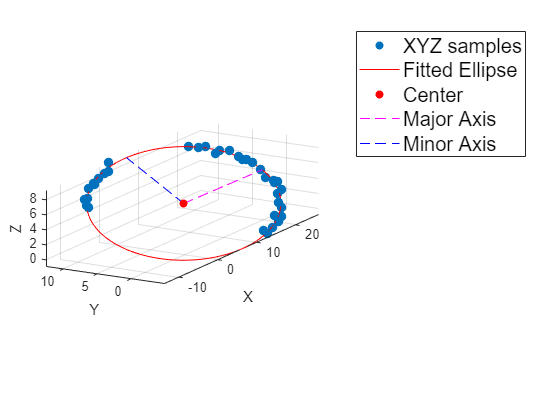


Center=pFit.unproject3D(eFit.center(:));
Vertex  =pFit.unproject3D( eFit.center(:)) + eFit.a*pFit.unproject3D( eFit.R(:,1) ,'direction');
CoVertex=pFit.unproject3D( eFit.center(:)) + eFit.b*pFit.unproject3D( eFit.R(:,2) ,'direction');

scatter(pFit); hold on
plot3(XYZ(1,:), XYZ(2,:), XYZ(3,:),'r-'); 
scatter3(Center(1)  , Center(2), Center(3),'filled','r');
plot3([Center(1), Vertex(1)]  , [Center(2), Vertex(2)], [Center(3), Vertex(3)] ,'m--');
plot3([Center(1), CoVertex(1)]  , [Center(2), CoVertex(2)], [Center(3), CoVertex(3)] ,'b--'); hold off
axis equal; view(-60,15); legend('XYZ samples','Fitted Ellipse','Center','Major Axis','Minor Axis','FontSize',15)